clc; close all; clearvars;

A = [linspace(0, 800, 2000), linspace(1e3, 1e5, 60)]';
m = length(A);
n = m;
A = spdiags(A, 0, m, n);

rng(100);
b = rand(m, 1);
c = rand(n, 1);

tol = 1e-8;
stol = 1e-12;
reorth = 2;
exres = true;
maxit = 80000;
maxcycle = 80;
show_info = true;
ks = [20, 40, 60];

[~, ~, ~, resvec1] = tricg(A, b, c, [], [], tol, maxit, exres=exres);

default_properties = {'defaultAxesFontSize', 'defaultAxesLineWidth', ...
    'defaultLineLineWidth'};

default_vals = {14, 1.5, 2};
set(0, default_properties, default_vals);

figure(Position=[180 120 800 600]);

semilogy(0:length(resvec1)-1, resvec1, LineStyle='-');
hold on;

lgd_title = cell(1, 1+length(ks));
lgd_title{1} = 'TriCG';

line_style = {'--', ':', '-.'};
for i = 1:length(ks)
    k = ks(i);
    p = k + 80;
    [~, ~, ~, resvec2] = tricgdr_two_stage(A, b, c, [], [], [k, 0], p, tol, maxcycle, ...
                        maxit=maxit, stol=stol, reorth=reorth, exres=exres, show_info=show_info);

    lgd_title{i+1} = sprintf('TriCG-DR$(%d,%d)\\,$', p, k);
    semilogy(0:length(resvec2)-1, resvec2, LineStyle=line_style{i});
end

singular triplets converge at 1th cycle, absolute residual = 7.040374e-19, and relative residual = 7.040374e-24.
singular triplets converge at 1th cycle, absolute residual = 5.111861e-21, and relative residual = 5.111861e-26.
singular triplets converge at 1th cycle, absolute residual = 7.230260e-19, and relative residual = 7.230260e-24.


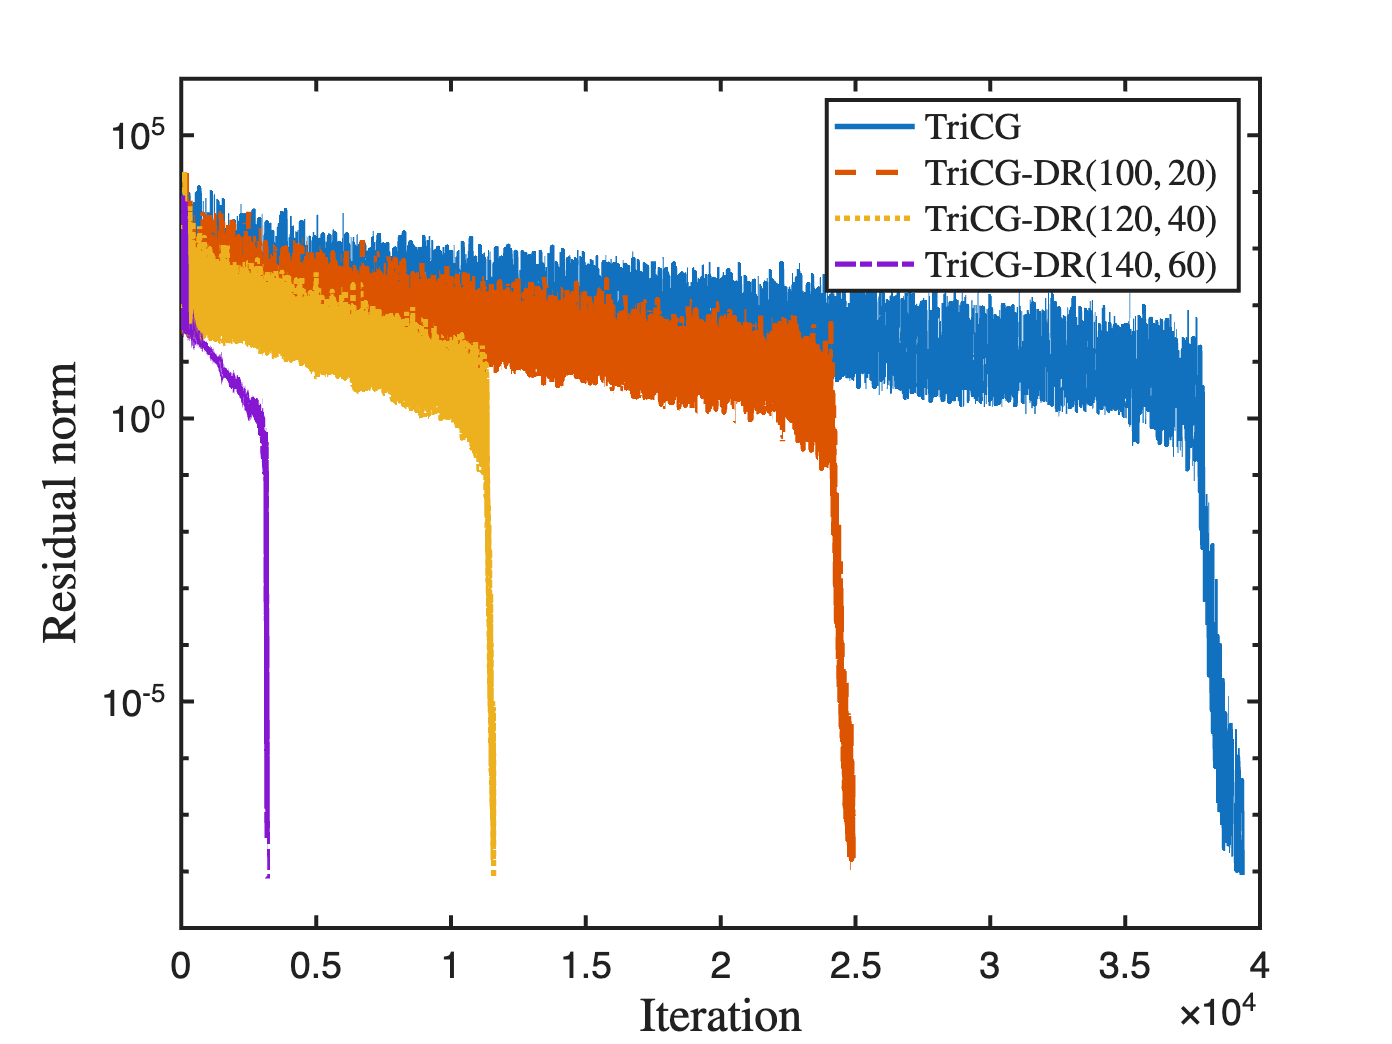

hold off;

ylim([1e-9, 1e6]);
xlabel('Iteration', Interpreter='latex', FontSize=18);
ylabel('Residual norm', Interpreter='latex', FontSize=18);
legend(lgd_title, Location='northeast', Interpreter='latex', FontSize=14);
exportgraphics(gcf, 'figs/fig1.pdf', Resolution=600);